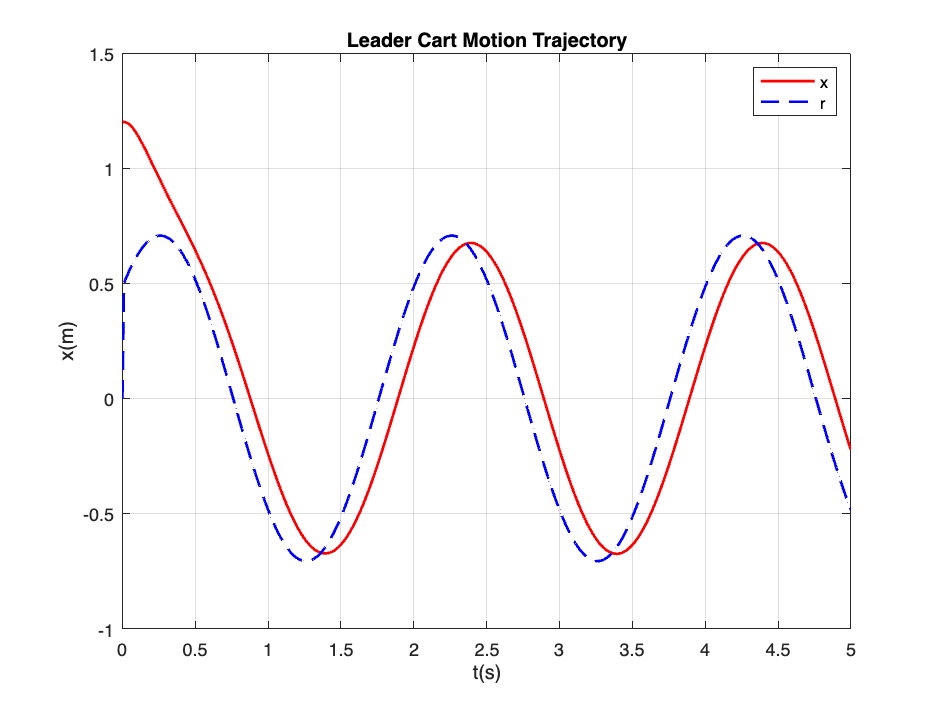

clear all; clc; clf();close all;
m = 0.5;%Mass of the cart, all carts have the same mass

%System state space setup
A_leader = [0 1;0 0]; B_leader = [0;1/m]; C_leader = [1 0]; D_leader = [0];
sys_leader = ss(A_leader,B_leader,C_leader,D_leader);

Q = 5; R = 0.02;

[Kx,S,P] = lqr(A_leader,B_leader,C_leader'*Q*C_leader,R);

%Desired time-varying position profile y_des = 0.5*cos(pi*t)+0.5*sin(pi*t)
%State variables: xr = [cos(pi*t);sin(pi*t)]
Ar = [0 -0.5*pi;0.5*pi 0]; Cr = [0.5 0.5];
As = (A_leader-B_leader*Kx)'; Bs = Ar; Cs = C_leader'*Q*Cr;
%Solve Sylvester equation for reference signal
W = sylvester(As,Bs,Cs);
Kxr = -inv(R)*B_leader'*W;

%Simulation Setup
ts = 0; t_final = 5;
dt = 0.01;
t = ts:dt:t_final;
x_leader = zeros(2,size(t,2));
y_leader = zeros(1,size(t,2));
yr_leader = zeros(1,size(t,2));
u_leader = zeros(1,size(t,2));
x_leader(:,1) = [1.2;0.2];
y_leader(:,1) = C_leader*x_leader(:,1);
%Simulation
for i = 2:size(t,2)
    %u(t) = −Kx*x(t) + Kxr*xr (t)
    u_leader(i-1) = -Kx*x_leader(:,i-1)+Kxr*[cos(pi*t(i-1));sin(pi*t(i-1))];
    x_leader(:,i) = inv(eye(2)-A_leader*dt/2)*(x_leader(:,i-1)+dt*(A_leader*x_leader(:,i-1)/2 ...
        +B_leader*u_leader(i-1)));
    y_leader(:,i) = C_leader*x_leader(:,i);
    yr_leader(:,i) = Cr*[cos(pi*t(i-1));sin(pi*t(i-1))];
end
u_leader(i) = u_leader(i-1);
figure(1);clf();
plot(t, y_leader, 'r',...
    t,yr_leader,'--b',...
'LineWidth', 1.5);
title('Leader Cart Motion Trajectory');
xlabel('t(s)'); ylabel('x(m)'); legend('x','r');
grid on

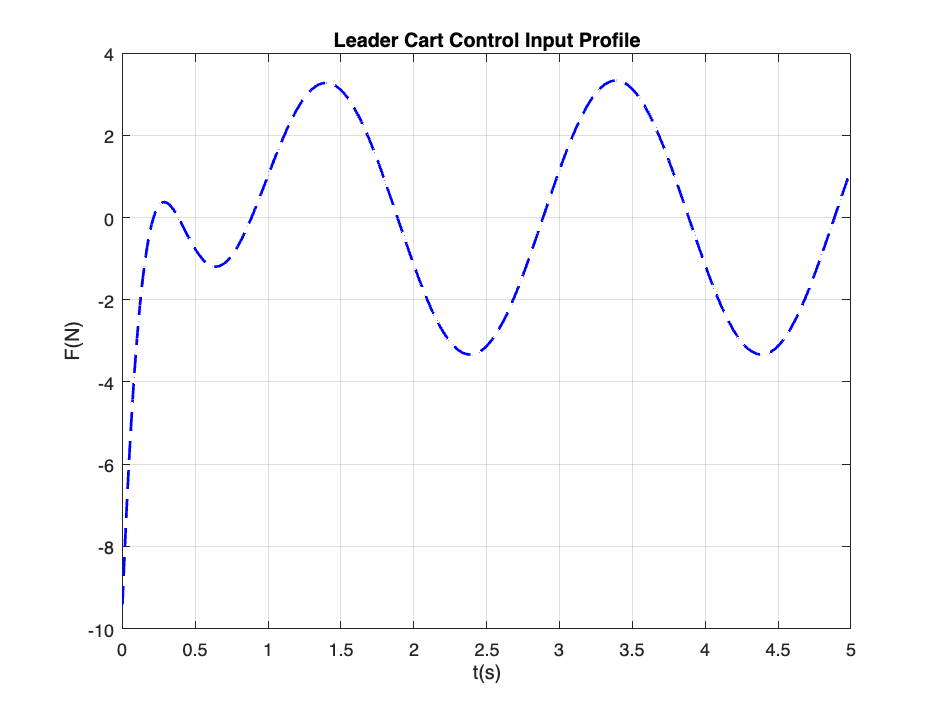


figure(2);clf();
plot(t, u_leader, '--b','LineWidth', 1.5);
title('Leader Cart Control Input Profile');
xlabel('t(s)');ylabel('F(N)');
grid on

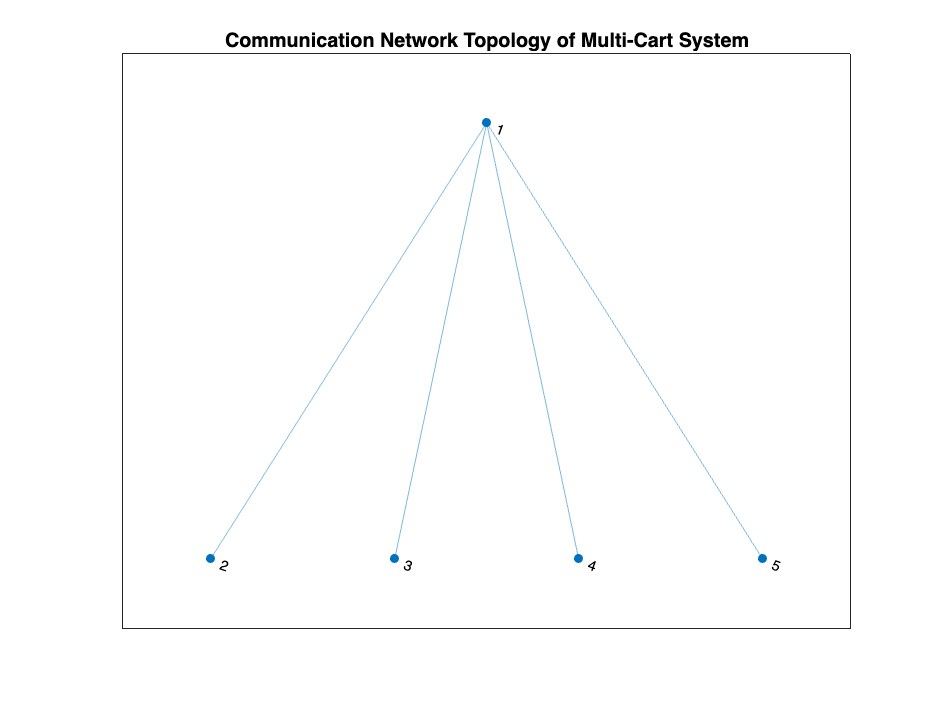


%Follower state space model, there are 4 follower carts in this
%multi-agent system
a_f = [0 1;0 0]; b_f = [0;1/m]; c_f = [1 0]; d_f = [0];
sys_follower = ss(a_f,b_f,c_f,d_f);

%General multi-agent system commnication network setup
G = graph([1,1,1,1],[2,3,4,5]);
figure(3);plot(G);title('Communication Network Topology of Multi-Cart System');

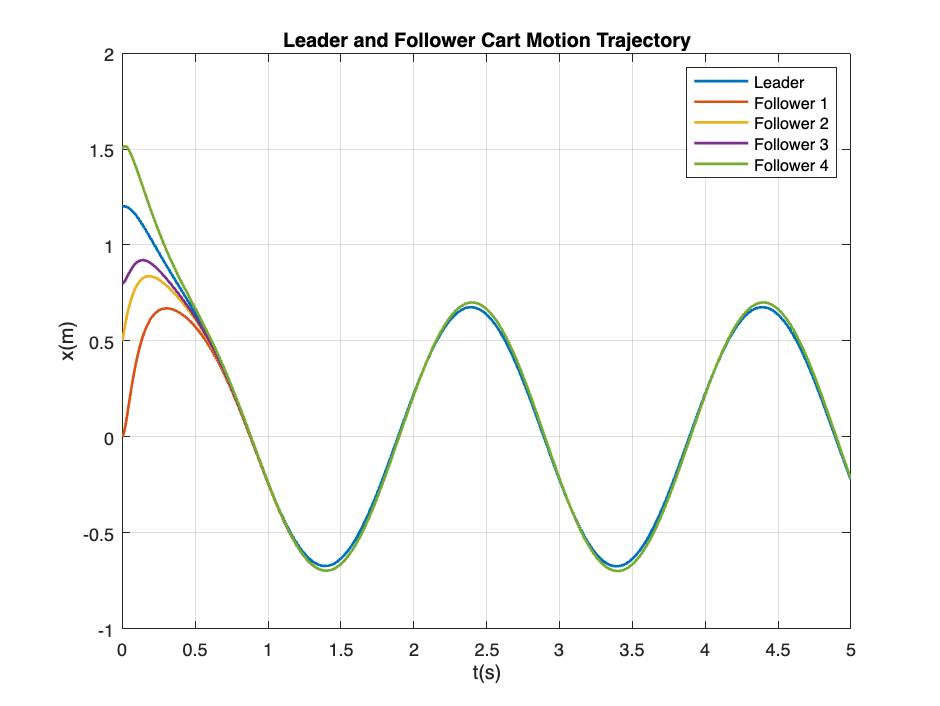

Adj = adjacency(G);
Dof = diag(degree(G));
L = Dof-Adj;
uf1 = zeros(1,size(t,2));
uf2 = zeros(1,size(t,2));
uf3 = zeros(1,size(t,2));
uf4 = zeros(1,size(t,2));
xf1 = zeros(2,size(t,2));
xf2 = zeros(2,size(t,2));
xf3 = zeros(2,size(t,2));
xf4 = zeros(2,size(t,2));
yf1 = zeros(1,size(t,2));
yf2 = zeros(1,size(t,2));
yf3 = zeros(1,size(t,2));
yf4 = zeros(1,size(t,2));
%Set initial condition of each follower cart
xf1(:,1) = [0;1]; xf2(:,1) = [0.5;5]; 
xf3(:,1) = [0.8;0]; xf4(:,1) = [1.5;2]; 
yf1(:,1) = c_f*xf1(:,1); yf2(:,1) = c_f*xf2(:,1); 
yf3(:,1) = c_f*xf3(:,1); yf4(:,1) = c_f*xf4(:,1); 
%Set leader cart index
leader_index = 1;
%Get number of carts in the multi-cart system
n_carts = size(Adj,1);
%Set weighting factor matrix v to adjust the
%consensus performance
v = -[100 20];
for i = 2:size(t,2)
    uf1(:,i-1) = uf1(:,i-1)+v*Adj(1,2)*(xf1(:,i-1)-x_leader(:,i-1));
    uf2(:,i-1) = uf2(:,i-1)+v*Adj(1,2)*(xf2(:,i-1)-x_leader(:,i-1));
    uf3(:,i-1) = uf3(:,i-1)+v*Adj(1,2)*(xf3(:,i-1)-x_leader(:,i-1));
    uf4(:,i-1) = uf4(:,i-1)+v*Adj(1,2)*(xf4(:,i-1)-x_leader(:,i-1));
    xf1(:,i) = inv(eye(2)-a_f*dt/2)*(xf1(:,i-1)+dt*(a_f*xf1(:,i-1)/2 ...
        +b_f*uf1(i-1)));
    yf1(:,i) = c_f*xf1(:,i);
    xf2(:,i) = inv(eye(2)-a_f*dt/2)*(xf2(:,i-1)+dt*(a_f*xf2(:,i-1)/2 ...
        +b_f*uf2(i-1)));
    yf2(:,i) = c_f*xf2(:,i);
    xf3(:,i) = inv(eye(2)-a_f*dt/2)*(xf3(:,i-1)+dt*(a_f*xf3(:,i-1)/2 ...
        +b_f*uf3(i-1)));
    yf3(:,i) = c_f*xf3(:,i);
    xf4(:,i) = inv(eye(2)-a_f*dt/2)*(xf4(:,i-1)+dt*(a_f*xf4(:,i-1)/2 ...
        +b_f*uf4(i-1)));
    yf4(:,i) = c_f*xf4(:,i);
end

figure(4);clf();
plot(t, y_leader, '-',...
    t,yf1,'-',...
    t,yf2,'-',...
    t,yf3,'-',...
    t,yf4,'-',...
'LineWidth', 1.5);
title('Leader and Follower Cart Motion Trajectory');
xlabel('t(s)'); ylabel('x(m)'); legend('Leader','Follower 1',...
    'Follower 2', 'Follower 3', 'Follower 4');
grid on

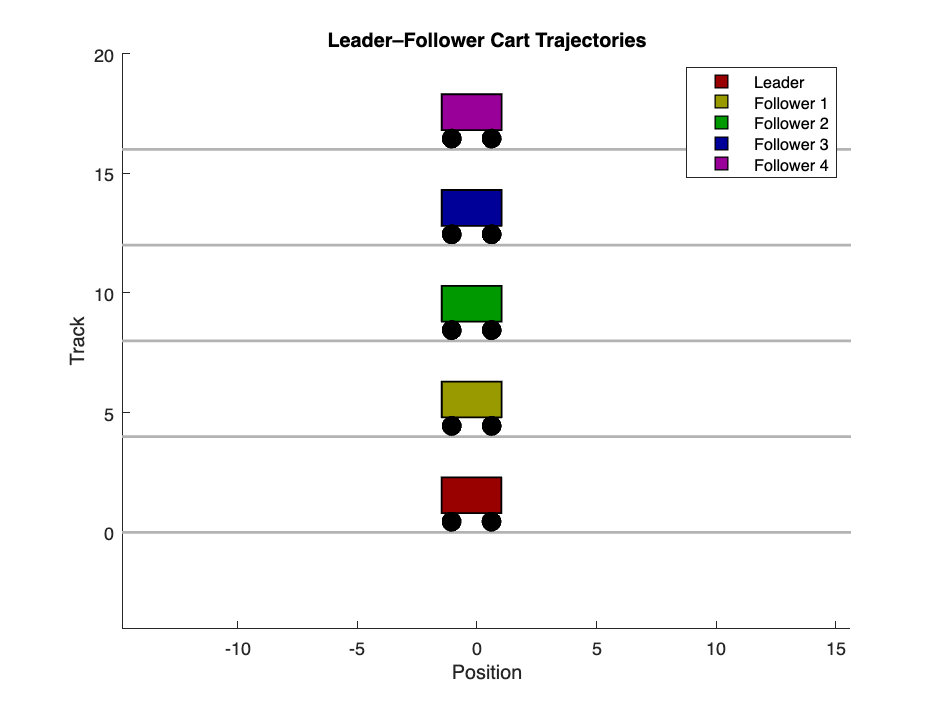


%Cart motion animation 
N = numel(t);
Y = {y_leader, yf1, yf2, yf3, yf4};
colors = { [0.6 0 0], ...    % dark red
           [0.6 0.6 0], ...  % dark yellow
           [0 0.6 0], ...    % dark green
           [0 0 0.6], ...    % dark blue
           [0.6 0 0.6] };    % dark magenta
cartLength = 2.5;    % along x‑axis
cartHeight = 1.5;    % along y‑axis
wheelDia    = 0.8;   % diameter
wheelRad    = wheelDia/2;
% Track layout
numCarts = numel(Y);
trackSpacing = 4;    % vertical distance between tracks
trackY = (0:numCarts-1) * trackSpacing;  % y‑positions of each track
% Leader on bottom → trackY(1)=0, followers above
cart_legend = ["Leader", "Follower 1", "Follower 2", "Follower 3", "Follower 4"];
figure(5); clf();
% Animation loop (or to just draw final positions comment this block out)
for i = 1:5:N  % skip frames for speed
    cla; 
    hold on;
    %Setup legends
    hLegend = gobjects(numel(Y),1);
    for k = 1:numel(Y)
    % A square marker just to show color/edge in legend:
    hLegend(k) = plot( NaN, NaN, 's', ...
        'MarkerSize', 10, ...
        'MarkerEdgeColor', 'k', ...
        'MarkerFaceColor', colors{k}, ...
        'LineWidth', 1, ...
        'DisplayName', cart_legend(k) );
    end
    % redraw tracks
    for k = 1:numCarts
        plot([min(cellfun(@min,Y)) - 10*cartLength, max(cellfun(@max,Y)) + 10*cartLength], ...
             trackY(k)*[1 1], 'Color',[0.7 0.7 0.7], 'LineWidth',1.5);
    end
    % draw each cart at time index i
    for k = 1:numCarts
        xC = Y{k}(i);      % cart center x-position
        yC = trackY(k)+cartHeight/2+wheelDia;    % track y-level
        
        % cart body rectangle
        xRect = xC - cartLength/2;
        yRect = yC - cartHeight/2;
        rectangle('Position',[xRect,yRect,cartLength,cartHeight], ...
                  'FaceColor',colors{k}, 'EdgeColor','k', 'LineWidth',1);
        % wheel positions: offset from body
        wxOffsets = [ -cartLength/3, +cartLength/3 ];
        wyOffset  = -cartHeight/2 - wheelRad + 0.05;
        for w = 1:2
            centerX = xC + wxOffsets(w);
            centerY = yC + wyOffset;
            theta = linspace(0,2*pi,50);
            xv = centerX + wheelRad*cos(theta);
            yv = centerY + wheelRad*sin(theta);
            patch(xv, yv, 'k');
        end
    end
    
    xlim([min(cellfun(@min,Y)) - cartLength, max(cellfun(@max,Y)) + cartLength]);
    ylim([trackY(1)-trackSpacing, trackY(end)+trackSpacing]);
    axis equal;
    xlabel('Position');
    ylabel('Track');
    legend(hLegend,cart_legend(1:5));
    title('Leader–Follower Cart Trajectories');

    drawnow;
end